load("et1_PSTH.mat")

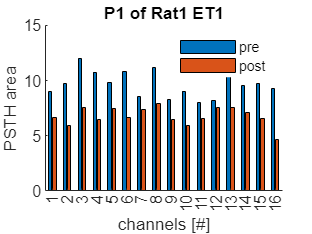

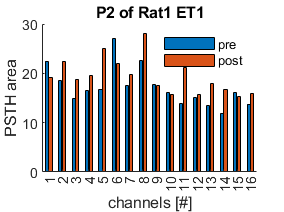

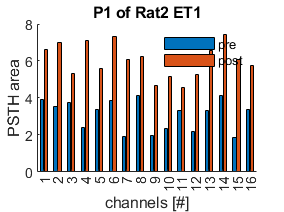

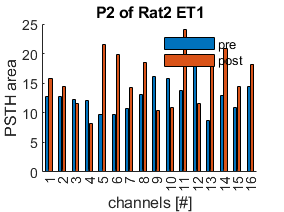

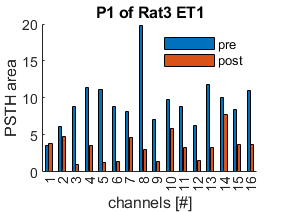

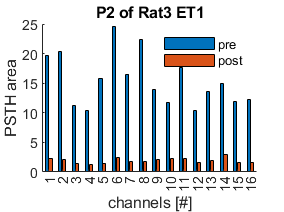

diff_perc=[];
area_pre=zeros(16,6);
area_post=zeros(16,6);
for column=1:6
        figure
        X=(0:length(et1_PSTH{1,1}(1,:))-1)*0.004;

        Int_pre=[];
        Int_post=[];

        for i=1:16
            Int_pre(end+1) = trapz(X, et1_PSTH{1,column}(i,:));
            Int_post(end+1) = trapz(X, et1_PSTH{2,column}(i,:));
        end
              
        bar([Int_pre' Int_post'])

        area_pre(:,column)=Int_pre';
        area_post(:,column)=Int_post';

        diff_perc=[diff_perc; ((Int_post-Int_pre)./Int_pre)*100]; %%---> correggi, la prof faceva (post-pre) diviso pre

        if mod(column,2) == 0
            ttl2=sprintf('P2');
        else
            ttl2=sprintf('P1');
        end

        switch column
            case 1 
                ttl3=sprintf('Rat1');
            case 2
                ttl3=sprintf('Rat1');
            case 3
                ttl3=sprintf('Rat2');
            case 4
                ttl3=sprintf('Rat2');
            case 5
                ttl3=sprintf('Rat3');
            case 6
                ttl3=sprintf('Rat3');
        end

        title(strcat(ttl2,{' of '},ttl3,{' ET1'}))
        xlabel('channels [#]')
        ylabel('PSTH area')
        xticks(1:16)
        legend('pre', 'post')
        legend boxoff
        box off

end

area_pre_tutti_et1_p1=reshape(area_pre(:,1:2:end),[],1);
save('area_pre_tutti_et1_p1.mat','area_pre_tutti_et1_p1','-v7.3')

area_post_tutti_et1_p1=reshape(area_post(:,1:2:end),[],1);
save('area_post_tutti_et1_p1.mat','area_post_tutti_et1_p1','-v7.3')

area_pre_tutti_et1_p2=reshape(area_pre(:,2:2:end),[],1);
save('area_pre_tutti_et1_p2.mat','area_pre_tutti_et1_p2','-v7.3')

area_post_tutti_et1_p2=reshape(area_post(:,2:2:end),[],1);
save('area_post_tutti_et1_p2.mat','area_post_tutti_et1_p2','-v7.3')

h =   Histogram with properties:

             Data: [-25.8089 -39.1638 -36.8006 -39.7921 -23.4241 -38.4796 -13.6538 -29.1850 -21.5350 -34.0762 -17.5873 -7.7870 -31.9579 -25.5347 -32.4545 -50.0672]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.0625 0 0.4375 0.3125 0.1250 0.0625 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


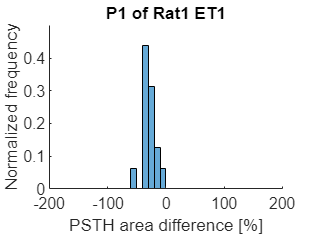

h =   Histogram with properties:

             Data: [-14.5653 21.1880 26.1889 18.6275 49.1439 -18.7748 13.0142 24.2203 -0.1088 -2.0796 52.7795 3.4681 32.8612 41.2666 -5.1470 16.0031]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.1250 0.1875 0.0625 0.1875 0.1875 0.0625 0.1250 0.0625 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


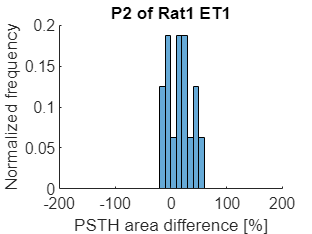

h =   Histogram with properties:

             Data: [67.7966 96.9555 42.0935 196.5278 64.3735 89.2241 216.4502 52.3327 136.9748 118.7943 36.7500 141.4449 97.9899 80.1095 229.7297 69.0418]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.0625 0.0625 0.0625 0.1875 0 0.1250 0.1250 0 0.0625 0 0.0625 0.0625 0 0 0 0 0.0625]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


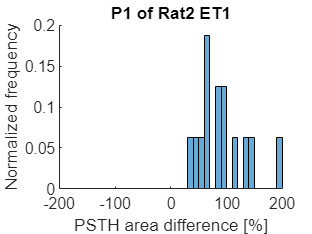

h =   Histogram with properties:

             Data: [23.3377 14.0328 -4.8630 -31.7712 123.0104 103.2391 32.0433 41.6162 -35.1323 -31.1146 74.2305 -37.6014 120.1543 61.9171 33.1288 26.3857]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.2500 0 0 0.0625 0 0.0625 0.1250 0.1250 0.0625 0 0.0625 0.0625 0 0 0.0625 0 0.1250 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


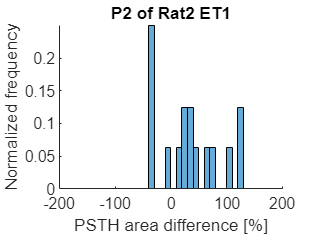

h =   Histogram with properties:

             Data: [7.6389 -21.9898 -88.6179 -68.9091 -88.2353 -83.1758 -41.7521 -84.9167 -81.0023 -39.0932 -62.9108 -75.7597 -71.9831 -22.9877 -55.4754 -66.8178]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0.3125 0.1250 0.1875 0.0625 0.0625 0.0625 0.1250 0 0 0.0625 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


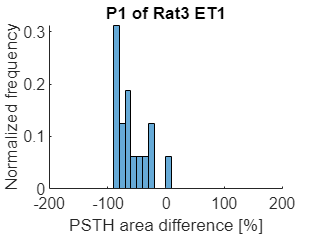

h =   Histogram with properties:

             Data: [-88.2925 -89.4715 -87.8990 -88.4185 -90.6399 -90.1623 -88.8721 -92.1160 -84.4031 -81.2588 -87.3823 -83.6834 -85.2349 -80.2668 -86.1130 -86.5937]
           Values: [0 0 0 0 0 0 0 0 0 0 0.1875 0.8125 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


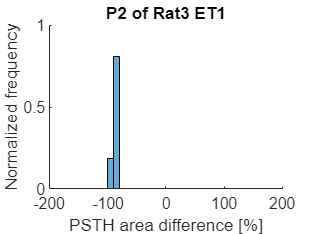

probabilita=[];
for i=1:6

    figure
    if mod(i,2) == 0
        ttl2=sprintf('P2');
    else
        ttl2=sprintf('P1');
    end

    switch i
        case 1
            ttl3=sprintf('Rat1');
        case 2
            ttl3=sprintf('Rat1');
        case 3
            ttl3=sprintf('Rat2');
        case 4
            ttl3=sprintf('Rat2');
        case 5
            ttl3=sprintf('Rat3');
        case 6
            ttl3=sprintf('Rat3');
    end

    h=histogram(diff_perc(i,:),'Normalization','probability','BinWidth',10,'BinLimits',[-200 200])
    probabilita=[probabilita;h.Values];

    xlim([-200 200])
    title(strcat(ttl2,{' of '},ttl3,{' ET1'}))
    xlabel('PSTH area difference [%]')
    ylabel('Normalized frequency')
    box off
end

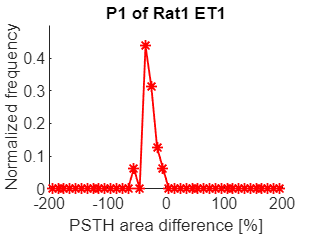

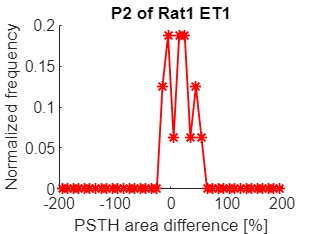

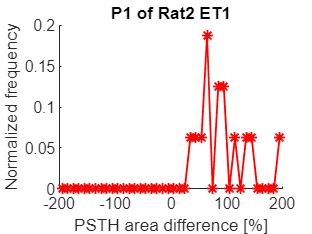

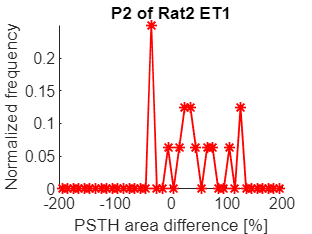

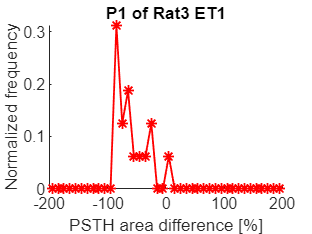

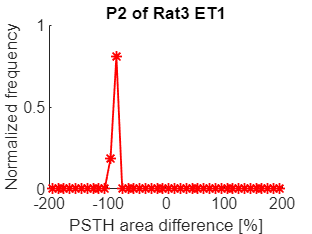

% plot istogrammi linee
x_axis=linspace(-200+10/2,200-10/2,40);
for i=1:6
    
    figure
    if mod(i,2) == 0
        ttl2=sprintf('P2');
    else
        ttl2=sprintf('P1');
    end

    switch i
        case 1
            ttl3=sprintf('Rat1');
        case 2
            ttl3=sprintf('Rat1');
        case 3
            ttl3=sprintf('Rat2');
        case 4
            ttl3=sprintf('Rat2');
        case 5
            ttl3=sprintf('Rat3');
        case 6
            ttl3=sprintf('Rat3');
    end

    plot(x_axis,probabilita(i,:),'*','color','r',LineStyle='-',LineWidth=1)
    

    xlim([-200 200])
    title(strcat(ttl2,{' of '},ttl3,{' ET1'}))
    xlabel('PSTH area difference [%]')
    ylabel('Normalized frequency')
    box off
end

all_rats_et1_P1=reshape(diff_perc(1:2:end,:),[],1);
save('all_rats_et1_P1.mat','all_rats_et1_P1','-v7.3')

all_rats_et1_P2=reshape(diff_perc(2:2:end,:),[],1);
save('all_rats_et1_P2.mat','all_rats_et1_P2','-v7.3')